# Adaptive matrix-weighted consensus with multiple unknown constant time delays

%% Initialization
clear all
clc
n = 9;
m = 14;
d = 3;
rng(5);

s = [1 1 2 2 3 3 4 4 5 5 6 7 7 8];
t = [2 3 3 4 4 5 5 6 7 9 7 8 9 9];
G = graph(s,t);
H = incidence(G)'*eye(9);
A12 = [1       sqrt(3)/2 0;
      sqrt(3)/2 1       0;
       0       0       0];
A13 = [0 0 0;
       0 1 0;
       0 0 1];
A23 = [2 1 0;
       1 1 0;
       0 0 1];
A24 = A13; A34 = A13;
A35 = [1 0 0;
       0 0 0;
       0 0 0];
A45 = diag([1, 2, 3]);
A78 = eye(3);
A79 = eye(3);
A89 = ones(3,3);
A46 = A89;
A67 = A12;
A57 = A35;
A59 = A13;
W = blkdiag(A12,A13,A23,A24,A34,A35,A45,A46,A57,A59,A67,A78,A79,A89);

Hbar = kron(H, eye(d));
L = Hbar'*W*Hbar;
H1 = [H(1:5,:); zeros(9,9)];
H2 = [zeros(5,9); H(6:10,:); zeros(4,9)];
H3 = [zeros(10,9); H(11:14,:)];
lambda = max(eig(L));
tauMax = pi/(2*lambda)

tauMax = 0.1579

Hbar1 = kron(H1,eye(d));
Hbar2 = kron(H2,eye(d));
Hbar3 = kron(H3,eye(d));
L1 = Hbar1'*W*Hbar1;
L2 = Hbar2'*W*Hbar2;
L3 = Hbar3'*W*Hbar3;
E=[eye(d*(n-1));-kron(ones(1,n-1),eye(d))];

x0 = [];       % the agents are initially located on the unit sphere
for i = 1:9
    r = 2*(rand(3,1) - 0.5);
    x0 = [x0; r/norm(r)];
end
a0 = ones(9,1);
lambda = max(eig(L));
tauMax = pi/(2*lambda)

tauMax = 0.1579

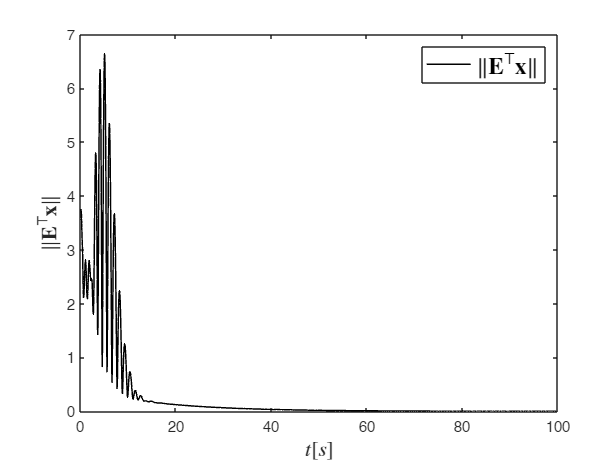

t_end = 100;
tau1 = 0.15;
tau2 = 0.25;
tau3 = 0.5;
% gamma = 0.25;

%% Simulation with Simulink
modelName = 'c12_AdapMultipleDelayConsensus';
sim(modelName);

%% Visualize the results
t = ans.ScopeData{1}.Values.Time;
x = ans.ScopeData{1}.Values.Data;
b = ans.ScopeData{2}.Values.Data;
a = zeros(length(t),9);
e = zeros(length(t),1);
for i = 1:length(t)
    c = b(:,:,i);
    for j = 1:9
        a(i,j) = c(j);
    end
    e(i,1) = norm(E'*x(i,:)',2);
end

figure
hold on
plot(t, e,'-k', "LineWidth", 1);
legend({'$\|\mathbf{E}^\top\mathbf{x}\|$'}, "Fontsize", 16, "Interpreter", "latex");
xlabel('$t [s]$',"Fontsize", 14, "Interpreter", "latex")
ylabel('$\|\mathbf{E}^\top\mathbf{x}\|$','FontSize', 14, "Interpreter", "latex")
box on

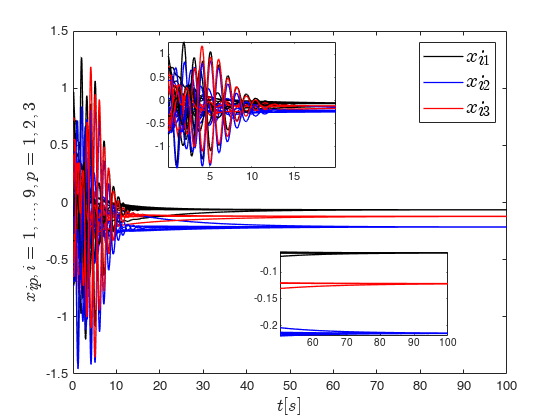

figure
hold on
for i = 1:9
    plot(t, x(:,3*i-2),'-k', "LineWidth", 1);
    plot(t, x(:,3*i-1),'-b', "LineWidth", 1);
    plot(t, x(:,3*i),'-r', "LineWidth", 1);
end
legend({'$x_{i1}$', '$x_{i2}$', '$x_{i3}$'}, "Fontsize", 16, "Interpreter", "latex");
xlabel('$t [s]$',"Fontsize", 14, "Interpreter", "latex")
ylabel('$x_{ip}, i=1,...,9, p=1,2,3$','FontSize', 14, "Interpreter", "latex")
box on

ax = axes('position',[0.3 .6 .3 .3]);
hold on
indexOfInterest = (t <= 20) & (t >= 0.01); % range of t near perturbation
for i = 1:9
    plot(t(indexOfInterest), x(indexOfInterest,3*i-2),'-k', "LineWidth", 1);
    plot(t(indexOfInterest), x(indexOfInterest,3*i-1),'-b', "LineWidth", 1);
    plot(t(indexOfInterest), x(indexOfInterest,3*i),'-r', "LineWidth", 1);
end
axis tight
box on;

ax = axes('position',[0.5 .2 .3 .2]);
box on % put box around new pair of axes
hold on
indexOfInterest = (t <= 100) & (t >= 50); % range of t near perturbation
for i = 1:9
    plot(t(indexOfInterest), x(indexOfInterest,3*i-2),'-k', "LineWidth", 1);
    plot(t(indexOfInterest), x(indexOfInterest,3*i-1),'-b', "LineWidth", 1);
    plot(t(indexOfInterest), x(indexOfInterest,3*i),'-r', "LineWidth", 1);
end
axis tight
box on;

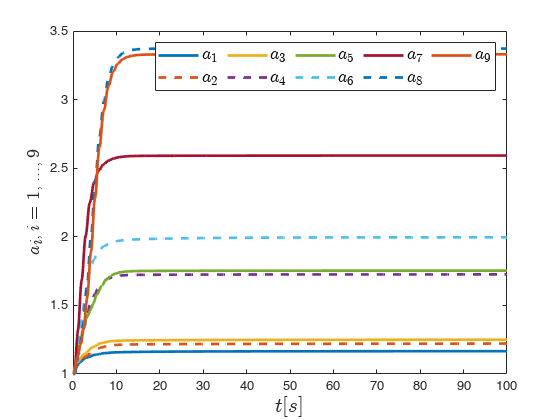

figure
hold on
for i=1:2:9
    plot(t, a(:,i),"LineWidth", 2);
    if i<9
        plot(t, a(:,i+1),"LineStyle","--","LineWidth", 2);
    end
end
legend({'$a_1$', '$a_2$', '$a_3$', '$a_4$', '$a_5$', '$a_6$','$a_7$', '$a_8$', '$a_9$'}, "Fontsize", 14, "NumColumns", 5, "Interpreter","latex");
xlabel('$t [s]$', "Fontsize", 16, "Interpreter", "latex");
ylabel('$a_i, i = 1,...,9$', "Fontsize", 14, "Interpreter", "latex");
box on